# ThingSpeak Workshop (2026)

## Tasks

- Create A Channel

- Read/Write Data to a Channel

- Understand the Channel Dashboard

- Read Multiple Data points

- Write/Read specific Fields

- Polling

- Two-way communication

- Turn-based Games - Handling Player Turn

## ThingSpeak

ThingSpeak allows you to store data as a table retrieve it, which in turn allows different apps to communicate remotely. In this tutorial, we will go through basic thingspeak commands to read/write different types of data and how to use them in simple applications.

## **Concepts**

**Channels : **Think of this as your cloud database. Stores streams of data as rows on a table. Once created, they remain active until they are manually deleted.

**Keys** : Passwords for access control. We need specific keys to have access to specific functionality 

**Name-Value Arguments : **As opposed to passing input arguments to a function via their position, we can also pass them via the argument name - by putting the argument name as a character array, followed by a comma and the intended value for the argument. Example:  `function('argument_name', value) `

## **Creating A Channel**

**Step 1.** Sign-in to your ThingSpeak account via [www.thingspeak.com](http://www.thingspeak.com) using the same email id+Password as your Matlab account.

**Step 2**. Create a new ThingSpeak channel. In the 'Channels' tab, click the green 'New Channel' button. Name the channel 'Tutorial' and enable the first four fields by checking the checkboxes next to them. Name the four fields `data1`, `data2`, `data3`, and `data4`. When using ThingSpeak for your own project, you can pick more meaningful names for any channel(s) you create. Also note the channel ID, as you will be using it later.

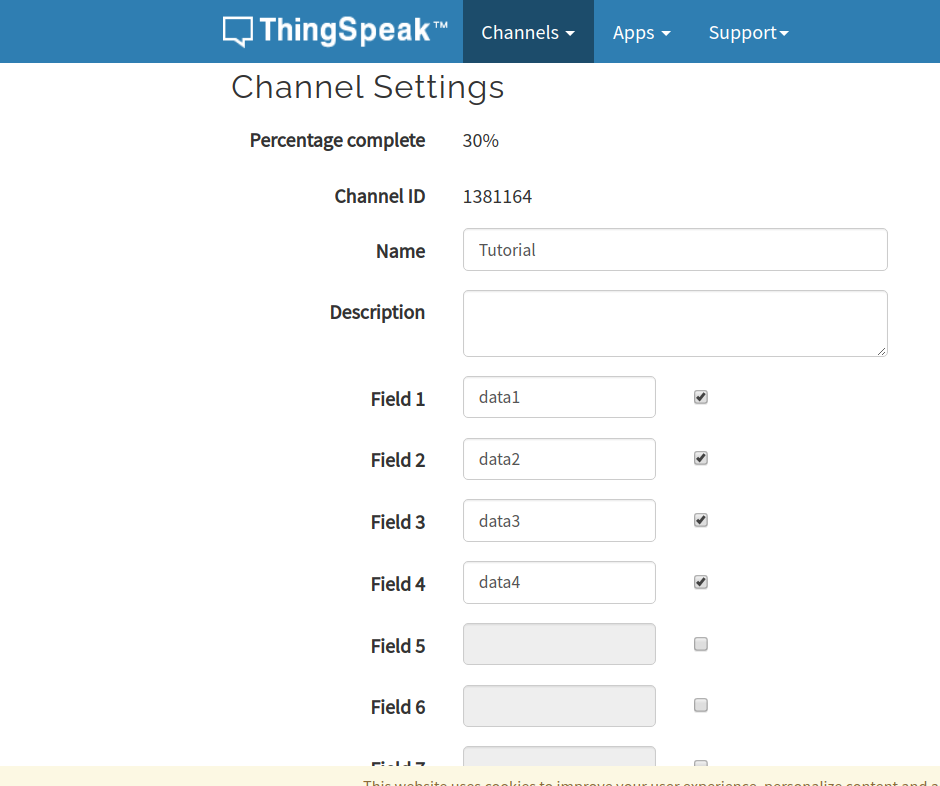

Next, click the API keys tab on your channel. Note the read and write API keys. You will be using these keys later.

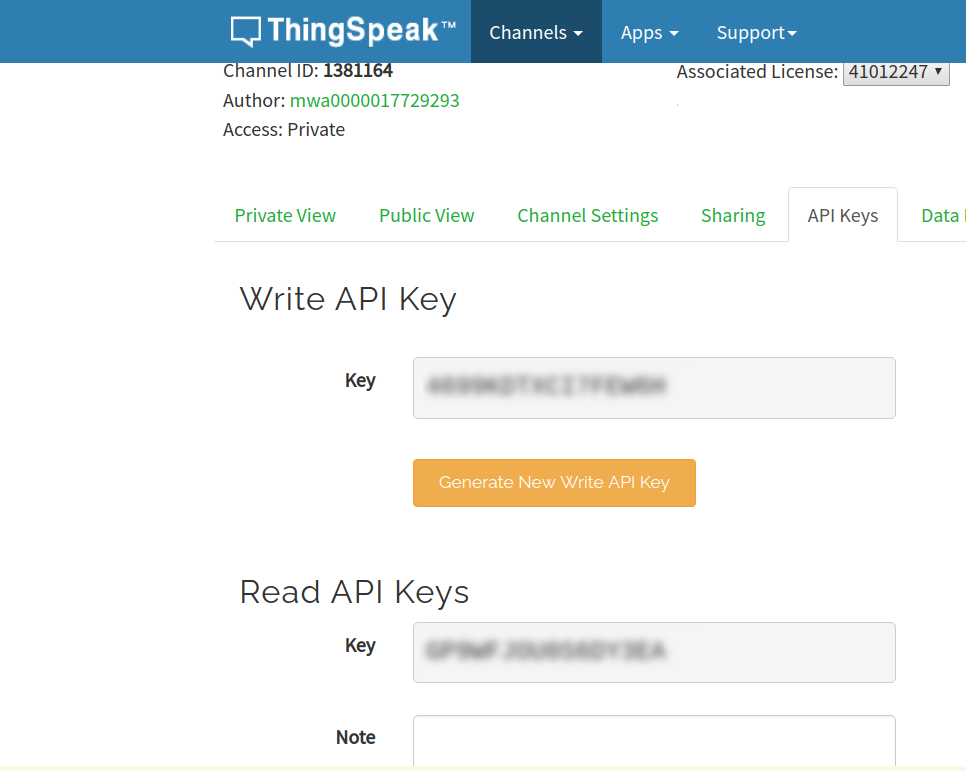

Finally, go to [https://thingspeak.com/account/profile,](https://thingspeak.com/account/profile,) and get the User API key.

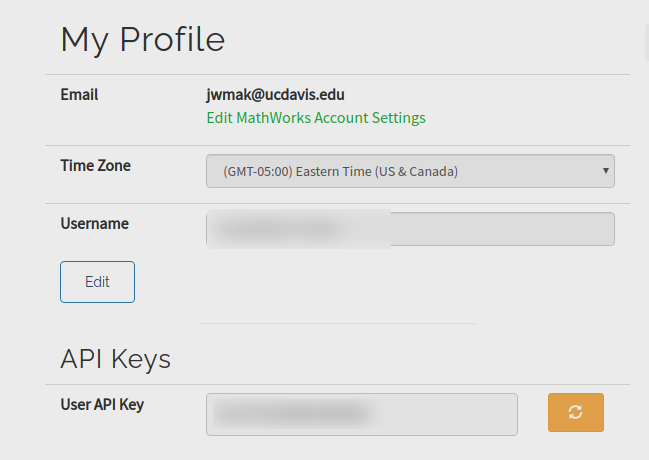

Store them somewhere for now - we will need them for the rest of the stpes

## Reading/Writing Data

**Functions**:  `thingSpeakRead` & `thingSpeakWrite` 

For more info check out the docs

[https://www.mathworks.com/help/thingspeak/thingspeakread.html](https://www.mathworks.com/help/thingspeak/thingspeakread.html)

[https://www.mathworks.com/help/thingspeak/thingspeakwrite.html](https://www.mathworks.com/help/thingspeak/thingspeakwrite.html)

% Setting up The channels
% Replace with your actual credentials
% Channels : https://thingspeak.mathworks.com/channels
channelID = 2863625; 
writeKey = 'KEY';
readKey  = 'KEY';
userAPIKey = 'API';  

Setup - 

% This code removes old data from the ThingSpeak channel
url = sprintf('https://api.thingspeak.com/channels/%s/feeds.json?api_key=%s', num2str(channelID), userAPIKey);
webwrite(url, weboptions('RequestMethod','delete'));

Imagine we are developing a Truck Delivery system that communicates with a central server every once in a while

Writing a single Row of data to the channel

% Example: The Truck sending GPS and Temperature data
lat = 30.2672;      % Latitude (Field 1)
lon = -97.7431;     % Longitude (Field 2)
tempF = 38.5;       % Temperature (Field 3)

% Send data to Fields 1, 2, and 3
thingSpeakWrite(channelID, [lat, lon, tempF], 'WriteKey', writeKey);

**What happens if a field is unspecified?** If you do not write to all fields, the other fields show `NaN` (Not a Number) for that specific timestamp. For example, here `Field4` will be NaN

Free ThingSpeak channels have a **rate limit**. You can only write to a channel once every **15 seconds**.

- If you try to send data every 1 second, the server will reject the request and throw a 'Too Frequent Requests' Error

- **Solution:** Use `pause(15)` in between any two consecutive write statements (Unless you have the Premium Version)

## Channel Dashboard

Each channel comes with a dashboard for data visualization. The dashboard also allows us to quickly debug data writes/reads.

To find this - go to [https://thingspeak.mathworks.com/channels/](https://thingspeak.mathworks.com/channels/) and click on your channel. It should pull up the following dashboard, along with a few other options

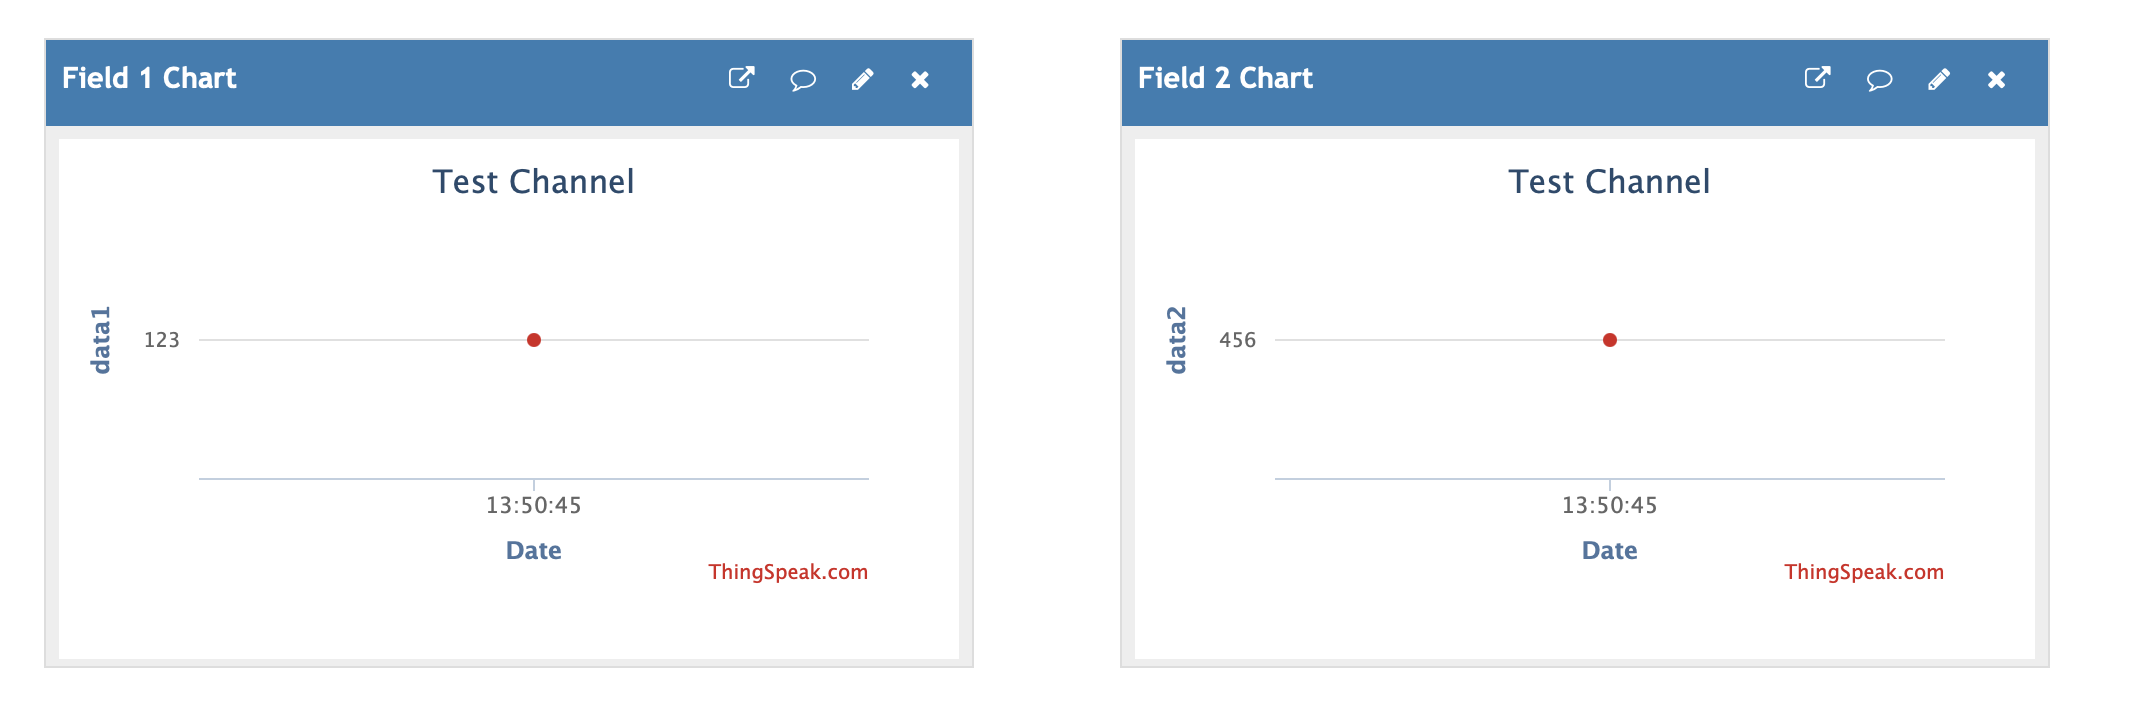

## Reading/Writing to Only Specific Fields

% Scenario: The truck is parked. We only want to update:
% Latitude (Field 1) and Engine Status (Field 4). 
% We are skipping Fields 2, and 3 entirely.

currentLat = 30.2672;
engineStatus = 0; % 0 for Off, 1 for On

% Use arrays for both the data and the Fields index
pause(15)
thingSpeakWrite(channelID, [currentLat, engineStatus], Fields=[1, 4], WriteKey=writeKey);

% Scenario: The dispatcher only wants to see location and status.
% We request Field 1 (Lat) and Field 4 (Status) specifically.

% data will be a matrix with 2 columns: [Field1, Field5]
[data, time] = thingSpeakRead(channelID, Fields=[1, 4], NumPoints=10, ReadKey=readKey);

% This signature lets you read the time associated with each data point

if ~isempty(data)
    latestLat = data(end, 1);    % First column requested
    latestStatus = data(end, 2); % Second column requested

    fprintf('Latest Latitude: %.4f | Engine Status: %d\n', latestLat, latestStatus);
end

Latest Latitude: 30.2672 | Engine Status: 0


## Reading Multiple Data Entries

We can either use the 'NumPoints' or the 'NumMinutes'/'NumDays' argument

% Get all data from the last 60 minutes to create a GPS trace
data = thingSpeakRead(channelID, 'ReadKey', readKey, 'NumMinutes', 60);

% If you just want the most recent 3 locations:
latest = thingSpeakRead(channelID, 'ReadKey', readKey, 'NumPoints', 3, 'OutputFormat', 'timetable');

% This one returns the data as a table! Print it out and see what it looks
% like. Each element within the table is going to be a cell

For even more advanced reads, you can apply a date range using the DateTime object

% Reading data off of a public channel
[data,timestamps,channelInfo] = thingSpeakRead(12397,Fields=[1 4], DateRange=[datetime(2018,8,9,23,59,01),datetime(2018,8,10,0,02,52)])

data =    NaN   NaN
   NaN   NaN
   NaN   NaN
   NaN   NaN


timestamps = 4×1 datetime array
   09-Aug-2018 23:59:06
   10-Aug-2018 00:00:06
   10-Aug-2018 00:01:07
   10-Aug-2018 00:02:08


channelInfo = struct with fields:
            ChannelID: 12397
                 Name: 'WeatherStation'
          Description: 'MathWorks Weather Station, West Garage, Natick, MA 01760, USA'
             Latitude: 42.2997
            Longitude: -71.3505
             Altitude: 60
              Created: 20-May-2014 14:50:32
              Updated: 02-Oct-2025 14:56:57
          LastEntryID: 5589743
    FieldDescriptions: {'Wind Direction (North = 0 degrees)'  'Wind Speed (mph)'  '% Humidity'  'Temperature (F)'  'Rain (Inches/minute)'  'Pressure ("Hg)'  'Power Level (V)'  'Light Intensity'}
             FieldIDs: [1 2 3 4 5 6 7 8]
                  URL: 'https://api.thingspeak.com/channels/12397/feed.json?'


## Checking For Updates

Checking for updates is simple. Read on a loop and see if anything changes. This trick is sometime called "Polling".

To see if a second instance (like a dispatcher) has received a **new**update from the truck, you compare the Last **Entry ID**.

Every time you write to ThingSpeak, the Last`EntryID` increases by 1.

% Instance 1: The Dispatcher checking for new truck updates
% This is another signature that gives you channel information
% Run this on a loop with some pause in between to avoid overloading the
% server
% while true
[data, time, info] = thingSpeakRead(channelID, 'ReadKey', readKey);

lastID = [];
if isempty(lastID)
    lastID = info.LastEntryID;
end

if info.LastEntryID > lastID
    disp('New data received from the truck!');
    lastID = info.LastEntryID; % Update the tracker
else
    disp('No new updates since last check.');
end

No new updates since last check.



% pause(15)
% end

## Two-Way Communication

In this scenario, **Instance A** (The Truck) writes fake sensor data, and **Instance B** (The Warehouse) reads it to decide if the dock is ready. 

Ideally the two following blocks of code should run in two separate instances of MATLAB (Must set the same ChannelIDs and API keys in both).

For now, we can run them one after another. 

This script allows you to effectively send data from one computer to another

Instance A (Truck Script):

for i = 1:5
    fakeTemp = 35 + randn(); % Generate fake temperature
    thingSpeakWrite(channelID, fakeTemp, 'Fields', 3, 'WriteKey', writeKey);
    fprintf('Truck sent temperature: %.2f\n', fakeTemp);
    pause(15); % Respect rate limiting
end

Requests are too frequent. For further information, see Limitations in the documentation.

Instance B (Warehouse Script):

% Read the last 5 minutes of temperature data
tempHistory = thingSpeakRead(channelID, 'Fields', 3, 'Minutes', 5, 'ReadKey', readKey);
avgTemp = mean(tempHistory, 'omitnan');

fprintf('Average cargo temperature for the last 5 mins: %.2f\n', avgTemp);

## Task

Co-ordinate with your partner. Run the above the above code and try to send data to your partner's ThingSpeak server.

*Note*: If you don't have a partner test this, you can run two MATLAB instances by yourself. One through the MATLAB Online and one through the Desktop App.

## Turn-based Games - Handling Player Turn (Template)

We can use Thingspeak as the IoT layer for simple turn-based games. There are many ways to go about building your perfect game. But for a simple multi-player game, typically you want to allow only one player to make a move at a time. Think Magic! The Gathering / Slay the Spire rather than Rivals. 

As with all things programming, there are many ways to implement this mechanic. The easiest way is to "sacrifice" one Thingspeak field to carry the active player ID. On the other side, we will initialize a unique playerID for each each player in the startUpFcn. 

Once the game begins, our app will have two states - Polling & Playing

In the polling stage, its the other players' turn to play. We pause our game and constantly check if the currentPlayerID has changed. If it has - we break out of the polling stage and move on to the playing stage. 

% Demo Polling Code - Goes into the a Relevant part in App Designer
% DO NOT RUN
app.myPlayerID    % Initialize this in startUpFcn
playerIDField = 1
while true
    currentPlayerID = hingSpeakRead(channelID, 'Fields', playerIDField);
    if currentPlayerID == app.myPlayerID
        break;
    end
    pause(1) % Not writing any data - don't need a 15s delay
end

## Final Notes

- Do not create more channels than necessary. For the Game groups, 